close all
clc
clear 
img = imread('lena.jpg');
img=double(img);
% 将图像分块传输（例如8x8块）
block_size = 8;
img_blocks = im2col(img, [block_size block_size], 'distinct');

% 随机丢弃30%的数据包
packet_loss_rate = 0.03;
loss_mask = rand(size(img_blocks)) > packet_loss_rate;
corrupted_blocks = img_blocks .* loss_mask;

% 重组图像
corrupted_img = col2im(corrupted_blocks, [block_size block_size], size(img), 'distinct');

% 显示
figure;
imshow(corrupted_img,[]);
title(['Packet Loss: ', num2str(packet_loss_rate*100), '%']);%%

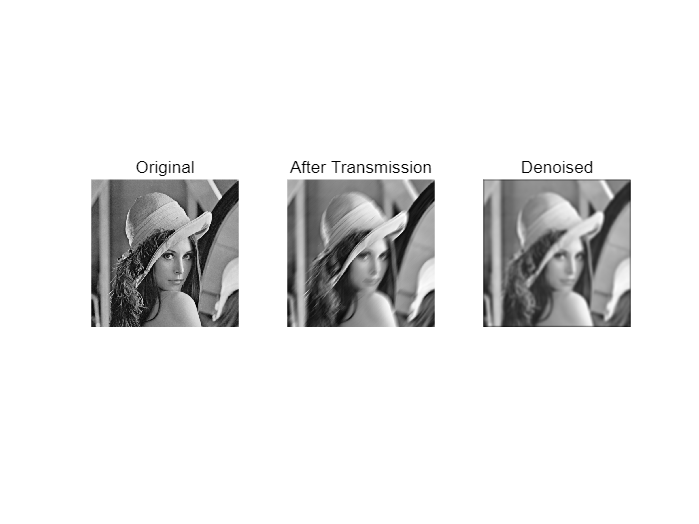

close all
clc
clear 
img = imread('lena.jpg');
img=double(img);

% 运动模糊（模拟传输抖动）
h_motion = fspecial('motion', 20, 45); % 长度20像素，角度45度
blurred_img = imfilter(img, h_motion, 'replicate');

% 高斯模糊（模拟频带限制）
h_gaussian = fspecial('gaussian', [15 15], 5);
gaussian_blurred = imfilter(img, h_gaussian);

% 对比显示
% montage({img, blurred_img, gaussian_blurred}, 'Size', [1 3]);%%
figure;
subplot(1,3,1), imshow(img,[]), title('Original');
subplot(1,3,2), imshow(blurred_img,[]), title('After Transmission');
subplot(1,3,3), imshow(gaussian_blurred,[]), title('Denoised');

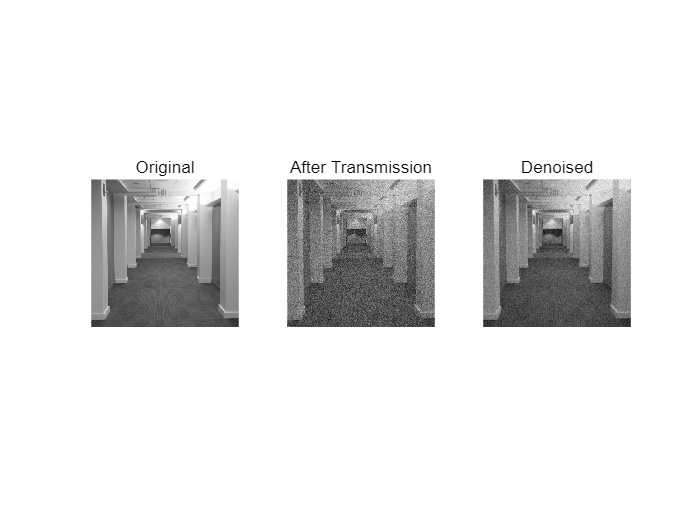

close all
clc
clear 
% 步骤1: 原始图像
img = im2double(imread('hallway.jpg'));

% 步骤2: JPEG压缩（模拟带宽限制）
imwrite(img, 'temp.jpg', 'Quality', 60);
compressed_img = imread('temp.jpg');

% 步骤3: 转换为信号并添加噪声
signal = compressed_img(:); % 图像转为信号
signal = double(signal);
snr = 15; % 信噪比15dB
noisy_signal = awgn(signal, snr, 'measured');

% 步骤4: 数据包丢失（模拟网络拥塞）
packet_size = 64; % 64字节/包
num_packets = floor(length(noisy_signal)/packet_size);
lost_packets = randperm(num_packets, floor(num_packets*0.1)); % 丢包率20%
noisy_signal(lost_packets*packet_size : (lost_packets+1)*packet_size) = 0;

% 步骤5: 恢复图像
rx_img = reshape(noisy_signal, size(compressed_img));
rx_img = im2double(rx_img);

% 步骤6: 解码后处理（去噪）
denoised_img = medfilt2(rx_img, [3 3]);

% 结果显示
figure;
subplot(1,3,1), imshow(img), title('Original');
subplot(1,3,2), imshow(rx_img,[]), title('After Transmission');
subplot(1,3,3), imshow(denoised_img,[]), title('Denoised');


%% 图像传输损伤模拟
clc; clear; close all;

% 读取原始图像
originalImg = imread('lena.jpg');
if size(originalImg,3)==3
    originalImg = rgb2gray(originalImg); % 转为灰度图
end
originalImg = im2double(originalImg);

%% 1. 高斯噪声模拟（热噪声）
noise_var = 0.02; % 噪声方差
gaussian_noise = imnoise(originalImg, 'gaussian', 0, noise_var);

%% 2. 椒盐噪声模拟（突发干扰）
density = 0.05; % 噪声密度
salt_pepper = imnoise(originalImg, 'salt & pepper', density);

%% 3. JPEG压缩模拟（有损压缩）
compression_quality = 10; % 压缩质量(1-100)
imwrite(originalImg, 'temp.jpg', 'Quality', compression_quality);
compressed_img = imread('temp.jpg');
delete('temp.jpg');

%% 4. 数据包丢失模拟（块效应）
packet_size = 8; % 块大小
loss_prob = 0.3; % 丢包概率
[rows, cols] = size(originalImg);
packet_loss = originalImg;

for i = 1:packet_size:rows
    for j = 1:packet_size:cols
        if rand() < loss_prob
            % 随机填充噪声块
            packet_loss(i:min(i+packet_size-1,rows),...
                      j:min(j+packet_size-1,cols)) = rand();
        end
    end
end

%% 5. 混合信道损伤模拟
combined_effect = imnoise(originalImg, 'gaussian', 0, 0.01);
combined_effect = imnoise(combined_effect, 'salt & pepper', 0.05);
combined_effect(1:2:end,1:2:end) = 0; % 亚采样损伤

%% 结果显示
figure;
subplot(2,3,1), imshow(originalImg), title('原始图像');
subplot(2,3,2), imshow(gaussian_noise), title(['高斯噪声 (σ²=',num2str(noise_var),')']);
subplot(2,3,3), imshow(salt_pepper), title(['椒盐噪声 (d=',num2str(density),')']);
subplot(2,3,4), imshow(compressed_img), title(['JPEG压缩 (q=',num2str(compression_quality),')']);
subplot(2,3,5), imshow(packet_loss), title(['块丢失 (p=',num2str(loss_prob),')']);
subplot(2,3,6), imshow(combined_effect), title('混合损伤');
